# Exercise 5

## Exercise 5.1

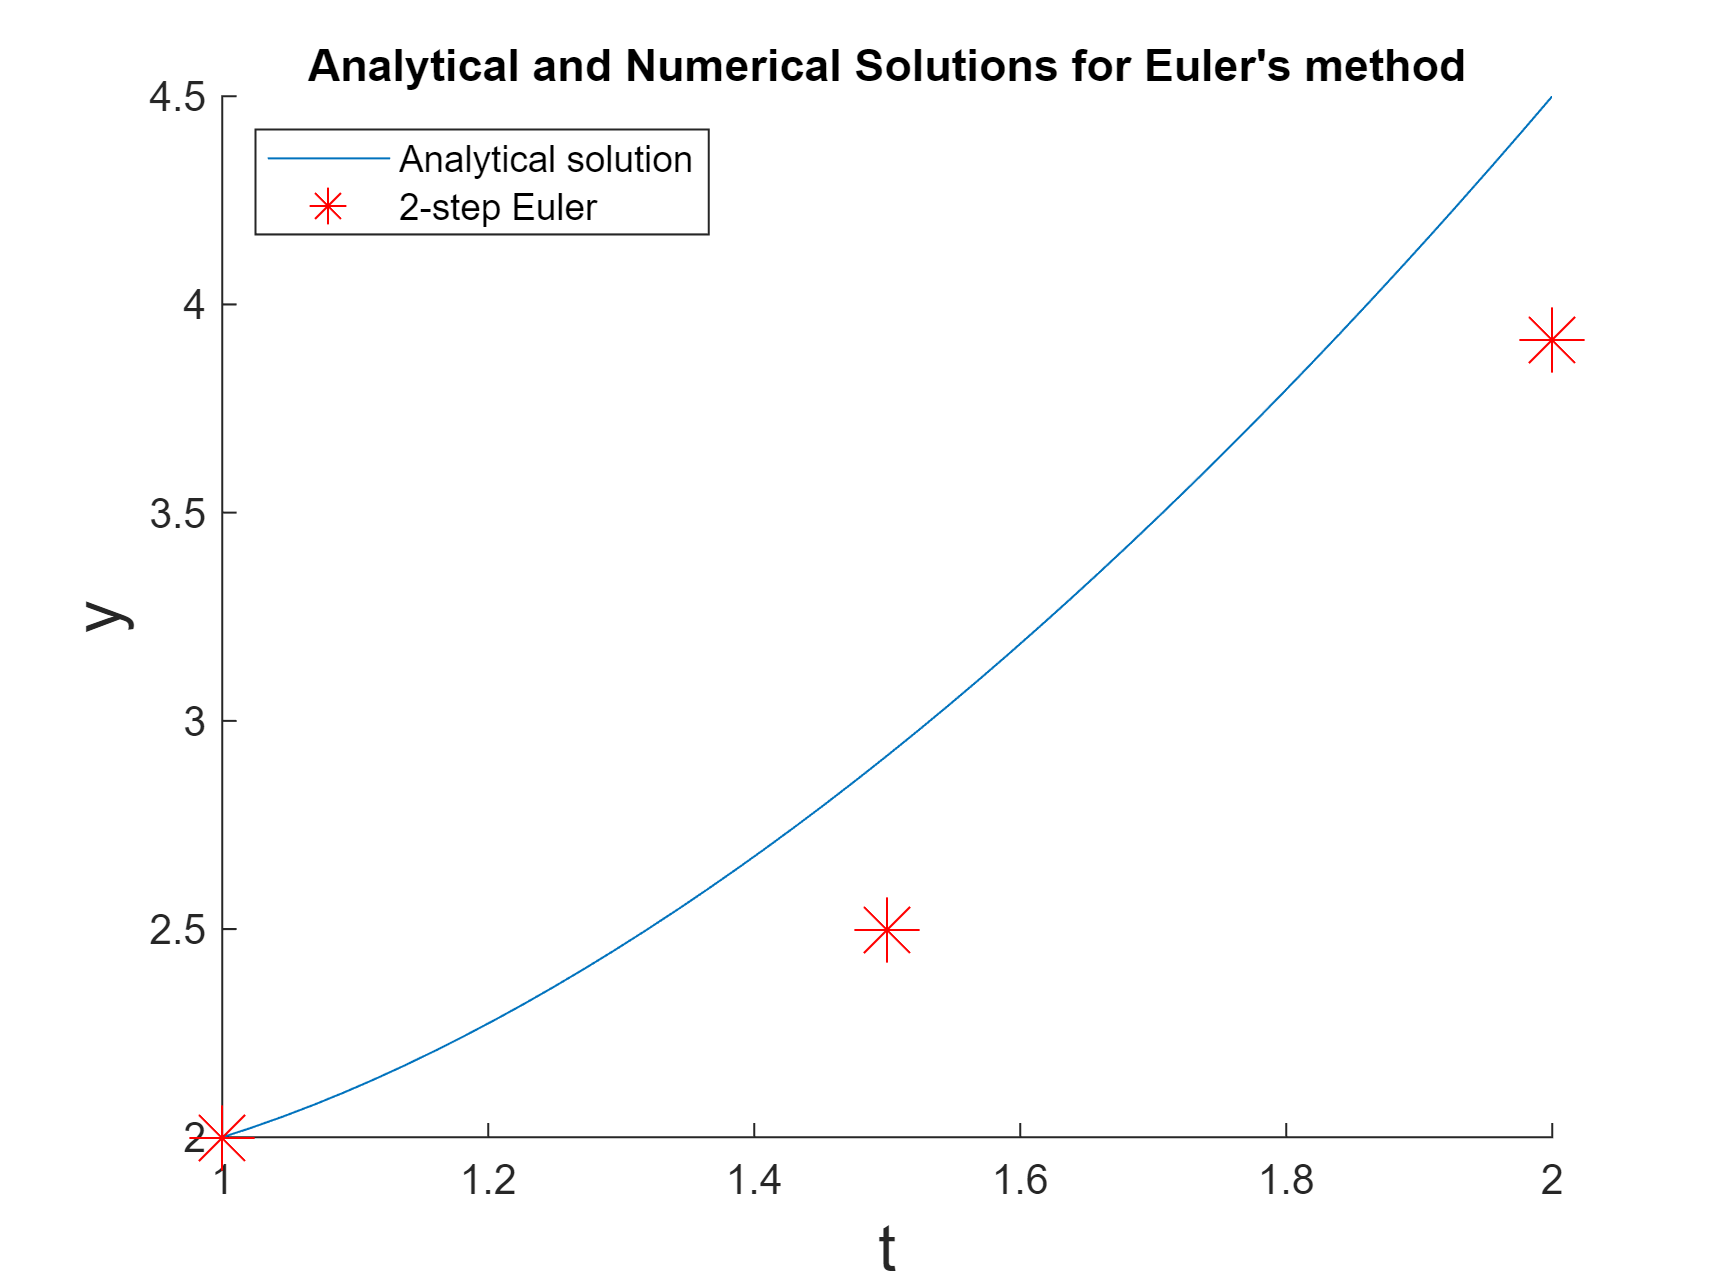

clear
close all
f = @(t, y) 3 * t - y ./ t;

a = 1; b = 2;

alpha = 2;
n = 2;
h = (b - a) / n;

t = a:h:b;

w = zeros(size(t));

w(1) = alpha;
for i = 1:n
    w(i + 1) = w(i) + h * f(t(i), w(i));
end

y = @(t) t.^2 + 1 ./ t;

figure
figure(1)
hold on 
fplot(y, [a, b])
plot(t, w, 'r*', 'MarkerSize', 16)
title('Analytical and Numerical Solutions for Euler''s method');
xlabel('t','FontSize',16); ylabel('y','FontSize',16);
legend('Analytical solution','2-step Euler','Location','NorthWest');

error2 = abs(w - y(t))

error2 =          0    0.4167    0.5833


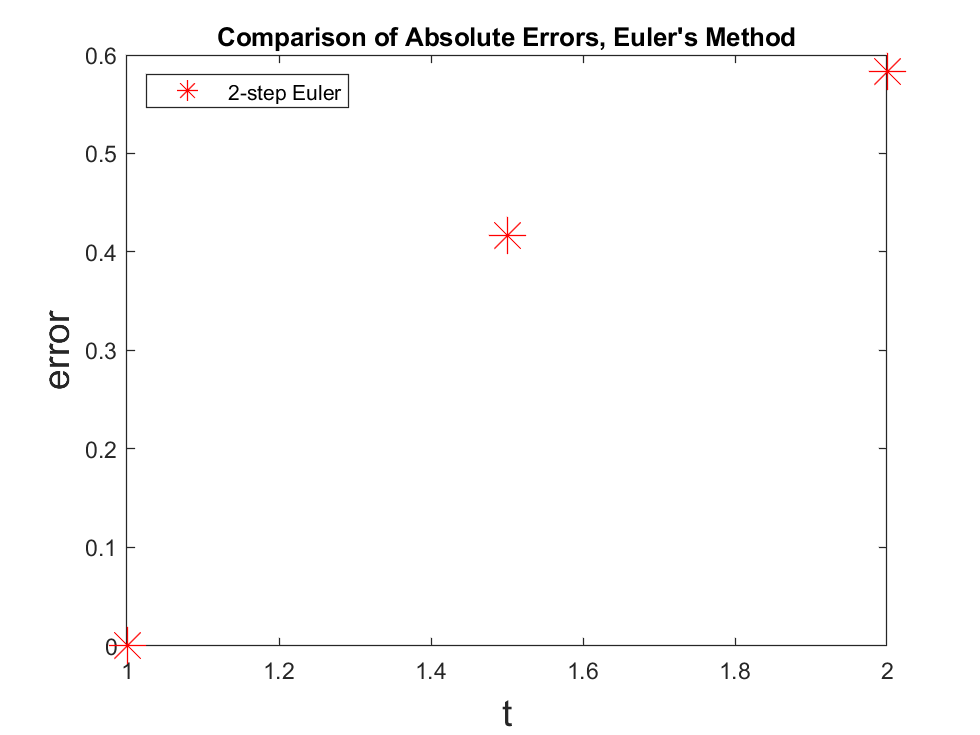

figure(2); 
plot(t, error2, 'r*', 'MarkerSize', 16);
title('Comparison of Absolute Errors, Euler''s Method');
xlabel('t','FontSize',16); ylabel('error','FontSize',16);
legend('2-step Euler','Location','NorthWest');

[t2, w2, h2] = euler_method(f, a, b, alpha, n)

t2 =     1.0000    1.5000    2.0000


w2 =     2.0000    2.5000    3.9167


h2 = 0.5000

n = 4; [t4, w4, h4] = euler_method(f, a, b, alpha, n)

t4 =     1.0000    1.2500    1.5000    1.7500    2.0000


w4 =     2.0000    2.2500    2.7375    3.4062    4.2321


h4 = 0.2500

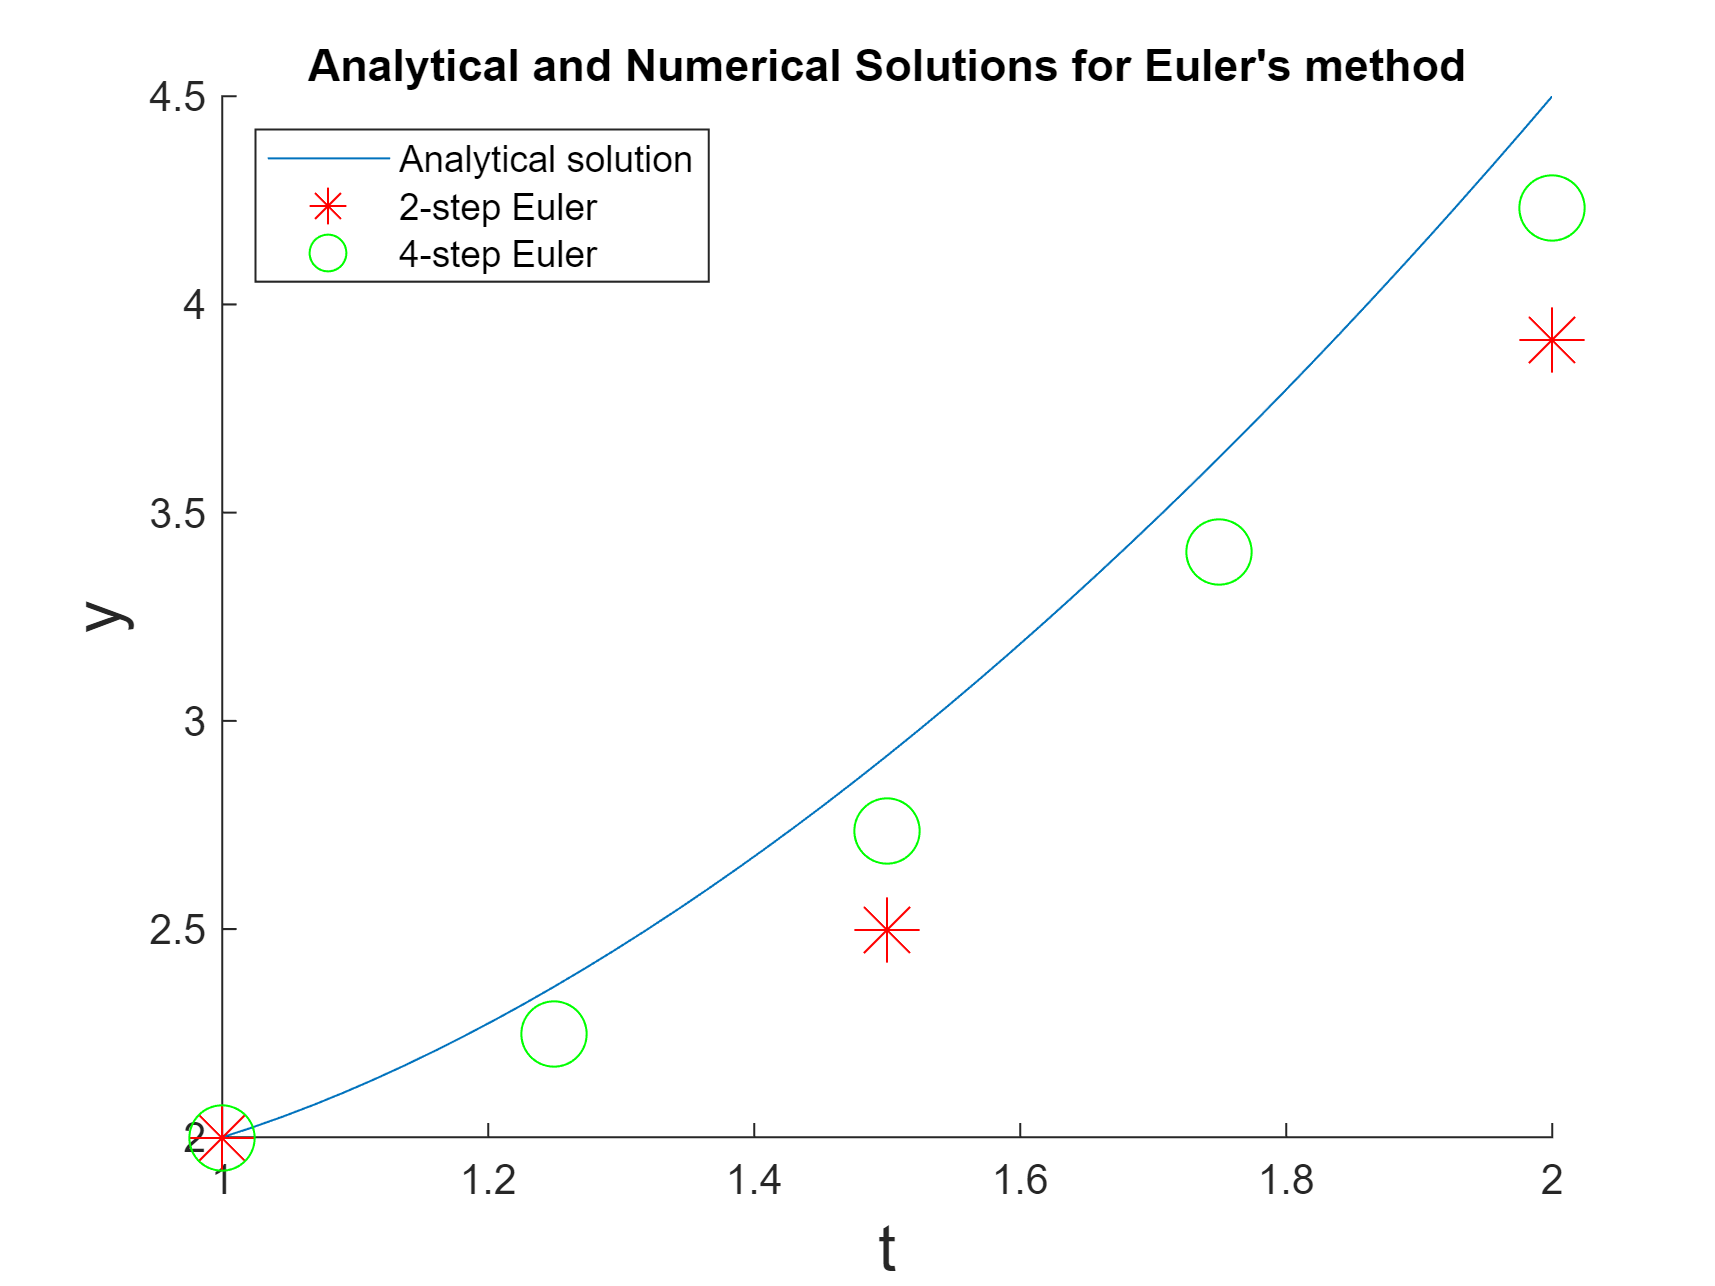

figure(1); 
plot(t4, w4, 'go', 'MarkerSize', 16)
legend('Analytical solution', '2-step Euler', '4-step Euler', 'Location', 'NorthWest')


error4 = abs(w4 - y(t4))

error4 =          0    0.1125    0.1792    0.2277    0.2679


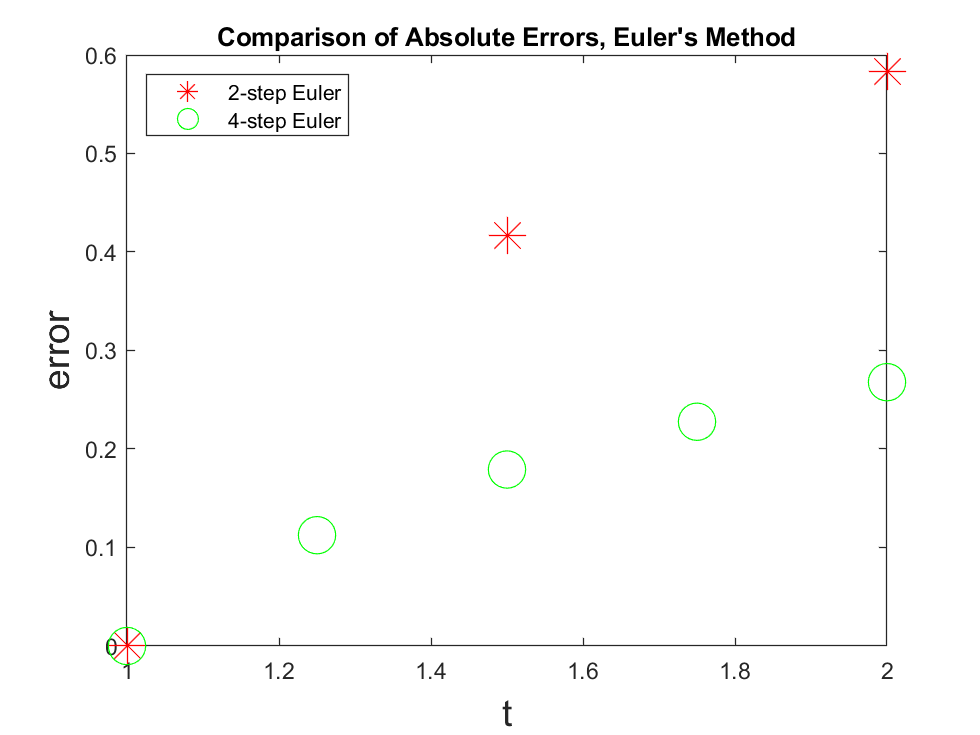

figure(2); hold on; plot(t4, error4, 'go', 'MarkerSize', 16)
legend('2-step Euler', '4-step Euler', 'Location', 'NorthWest')

n = 8; [t8, w8, h8] = euler_method(f, a, b, alpha, n)

t8 =     1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000


w8 =     2.0000    2.1250    2.3108    2.5484    2.8324    3.1589    3.5252    3.9297    4.3708


h8 = 0.1250

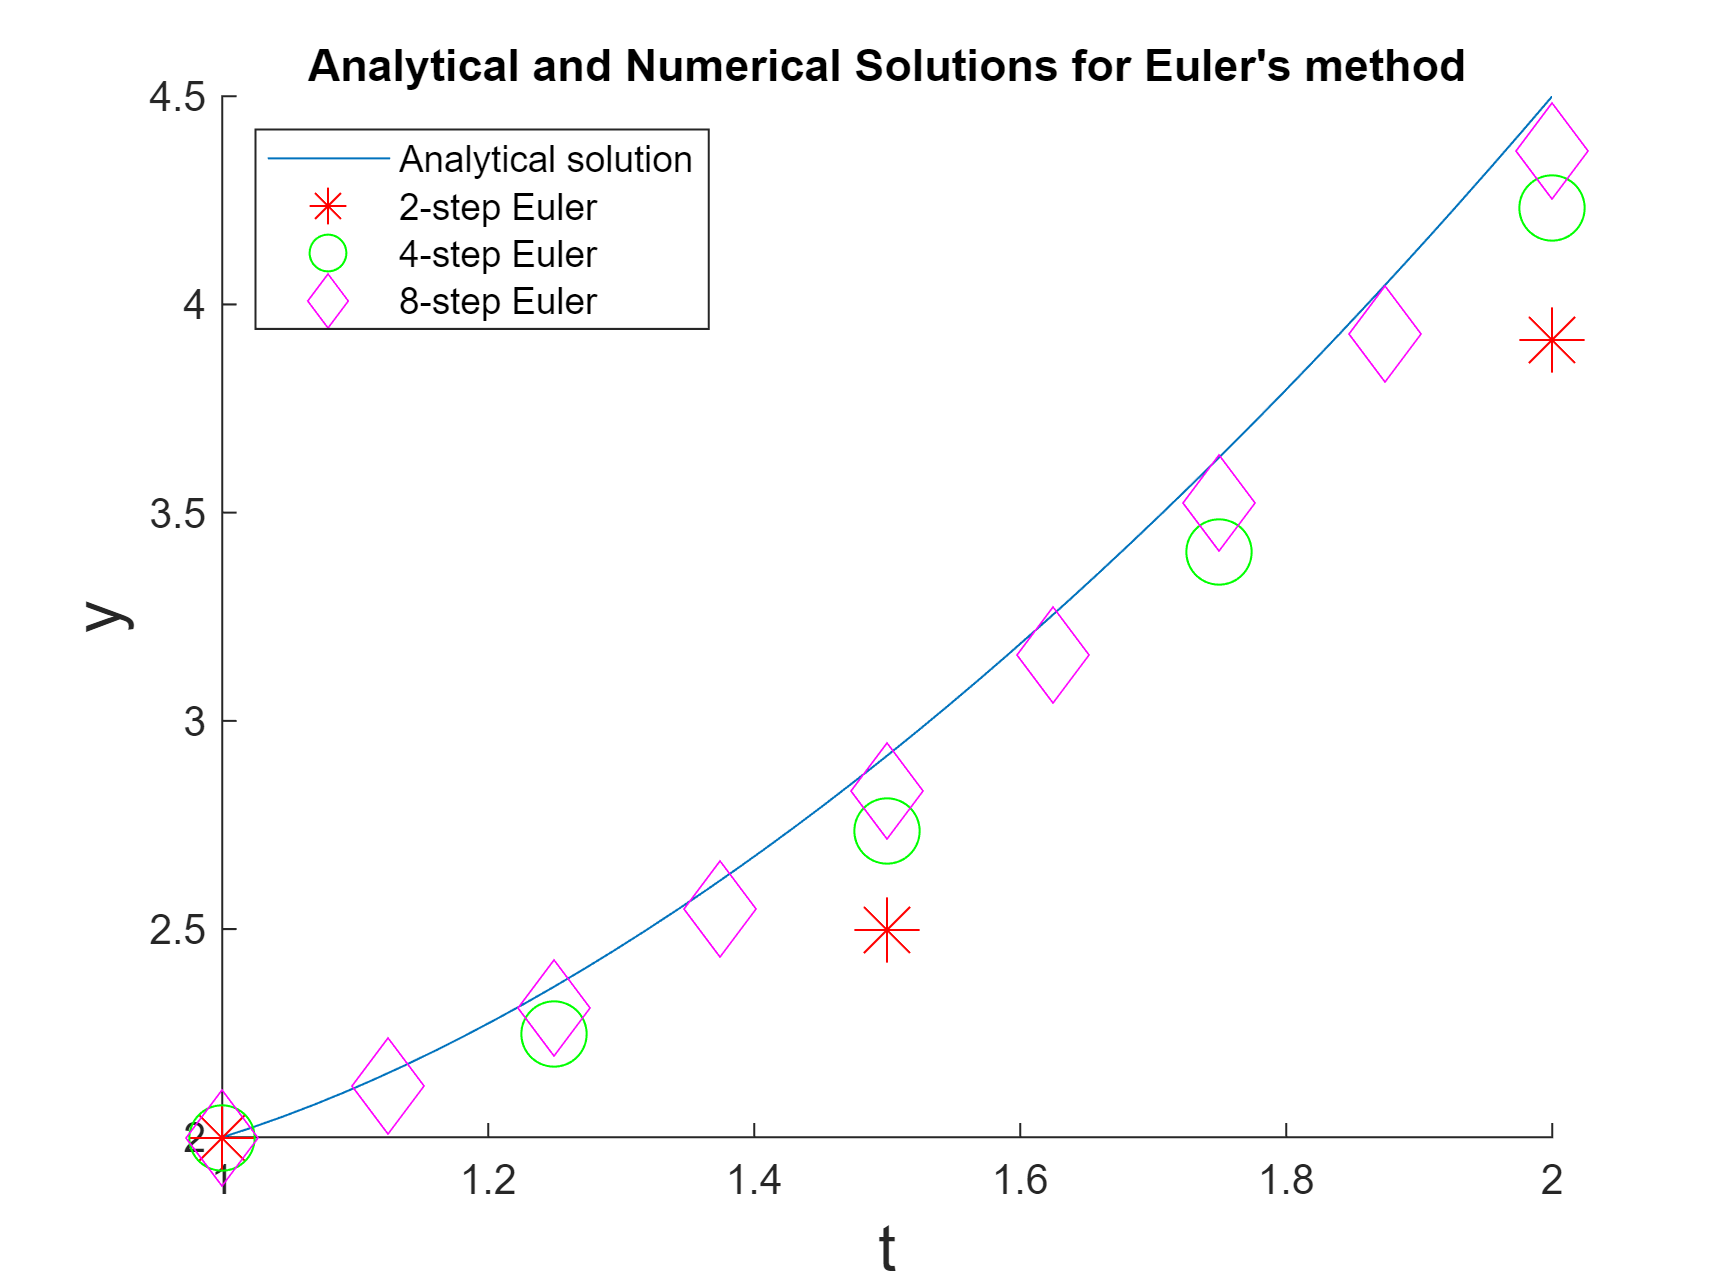

figure(1); 
plot(t8, w8, 'md', 'MarkerSize', 16)
legend('Analytical solution', '2-step Euler', '4-step Euler', '8-step Euler', 'Location', 'NorthWest')


error8 = abs(w8 - y(t8))

error8 =          0    0.0295    0.0517    0.0695    0.0843    0.0972    0.1087    0.1193    0.1292


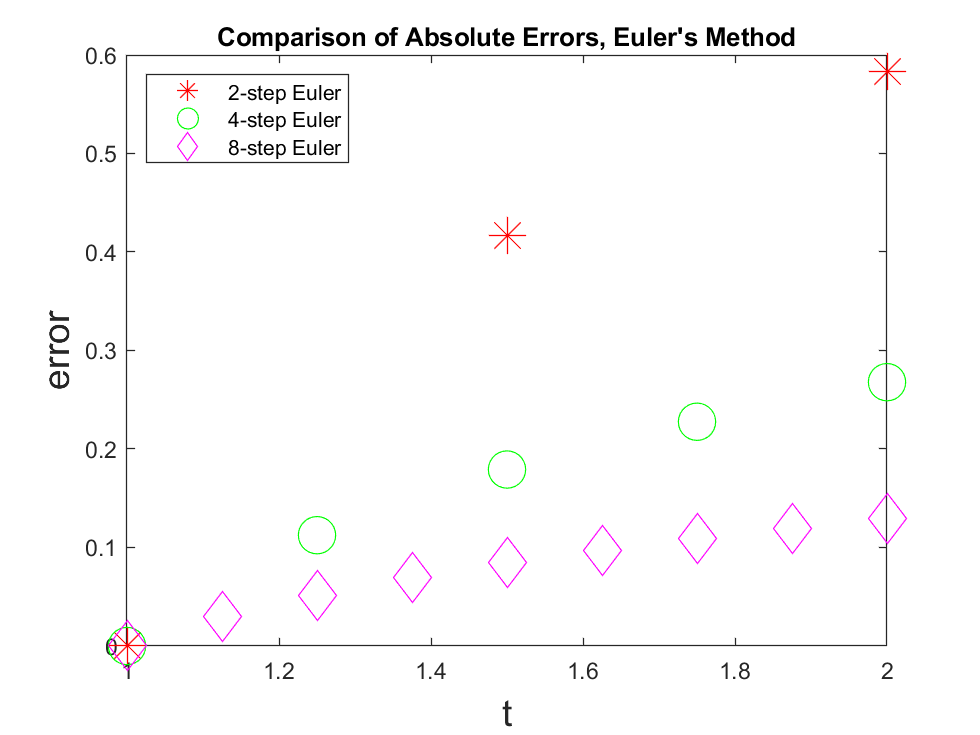

figure(2); hold on; plot(t8, error8, 'md', 'MarkerSize', 16)
legend('2-step Euler', '4-step Euler', '8-step Euler', 'Location', 'NorthWest')

n = 16; [t16, w16, h16] = euler_method(f, a, b, alpha, n)

t16 =     1.0000    1.0625    1.1250    1.1875    1.2500    1.3125    1.3750    1.4375    1.5000    1.5625    1.6250    1.6875    1.7500    1.8125    1.8750    1.9375    2.0000


w16 =     2.0000    2.0625    2.1404    2.2324    2.3376    2.4551    2.5843    2.7246    2.8757    3.0371    3.2086    3.3899    3.5807    3.7810    3.9904    4.2090    4.4365


h16 = 0.0625

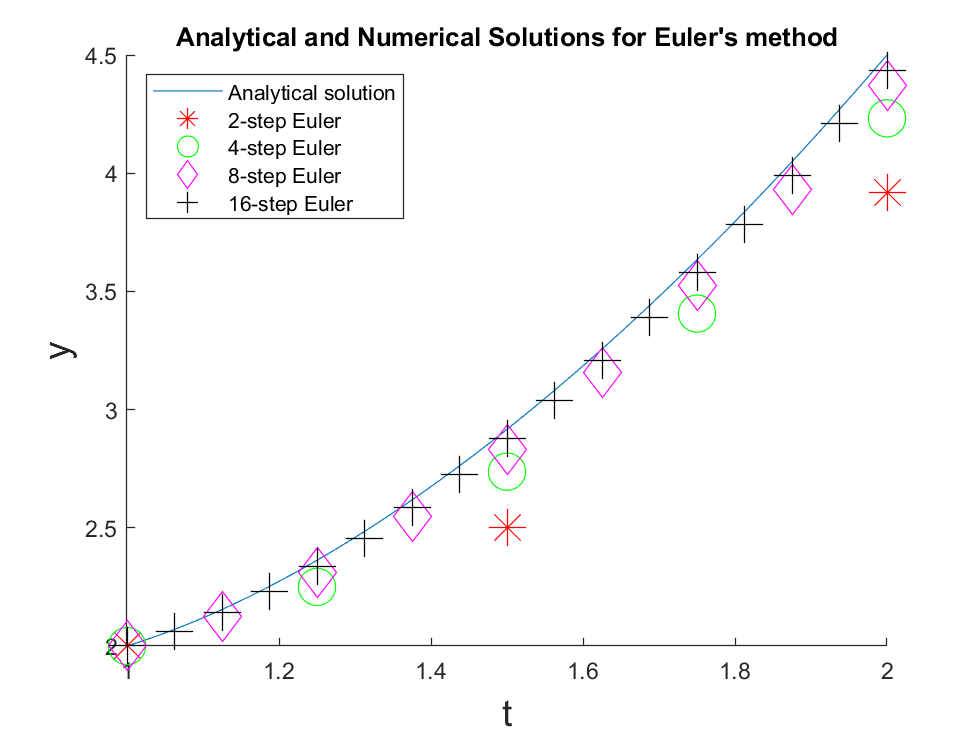

figure(1); 
plot(t16, w16, 'k+', 'MarkerSize', 16)
legend('Analytical solution', '2-step Euler', '4-step Euler', '8-step Euler', '16-step Euler', 'Location', 'NorthWest')


error16 = abs(w16 - y(t16))

error16 =          0    0.0076    0.0141    0.0198    0.0249    0.0295    0.0336    0.0374    0.0410    0.0443    0.0474    0.0504    0.0532    0.0559    0.0585    0.0611    0.0635


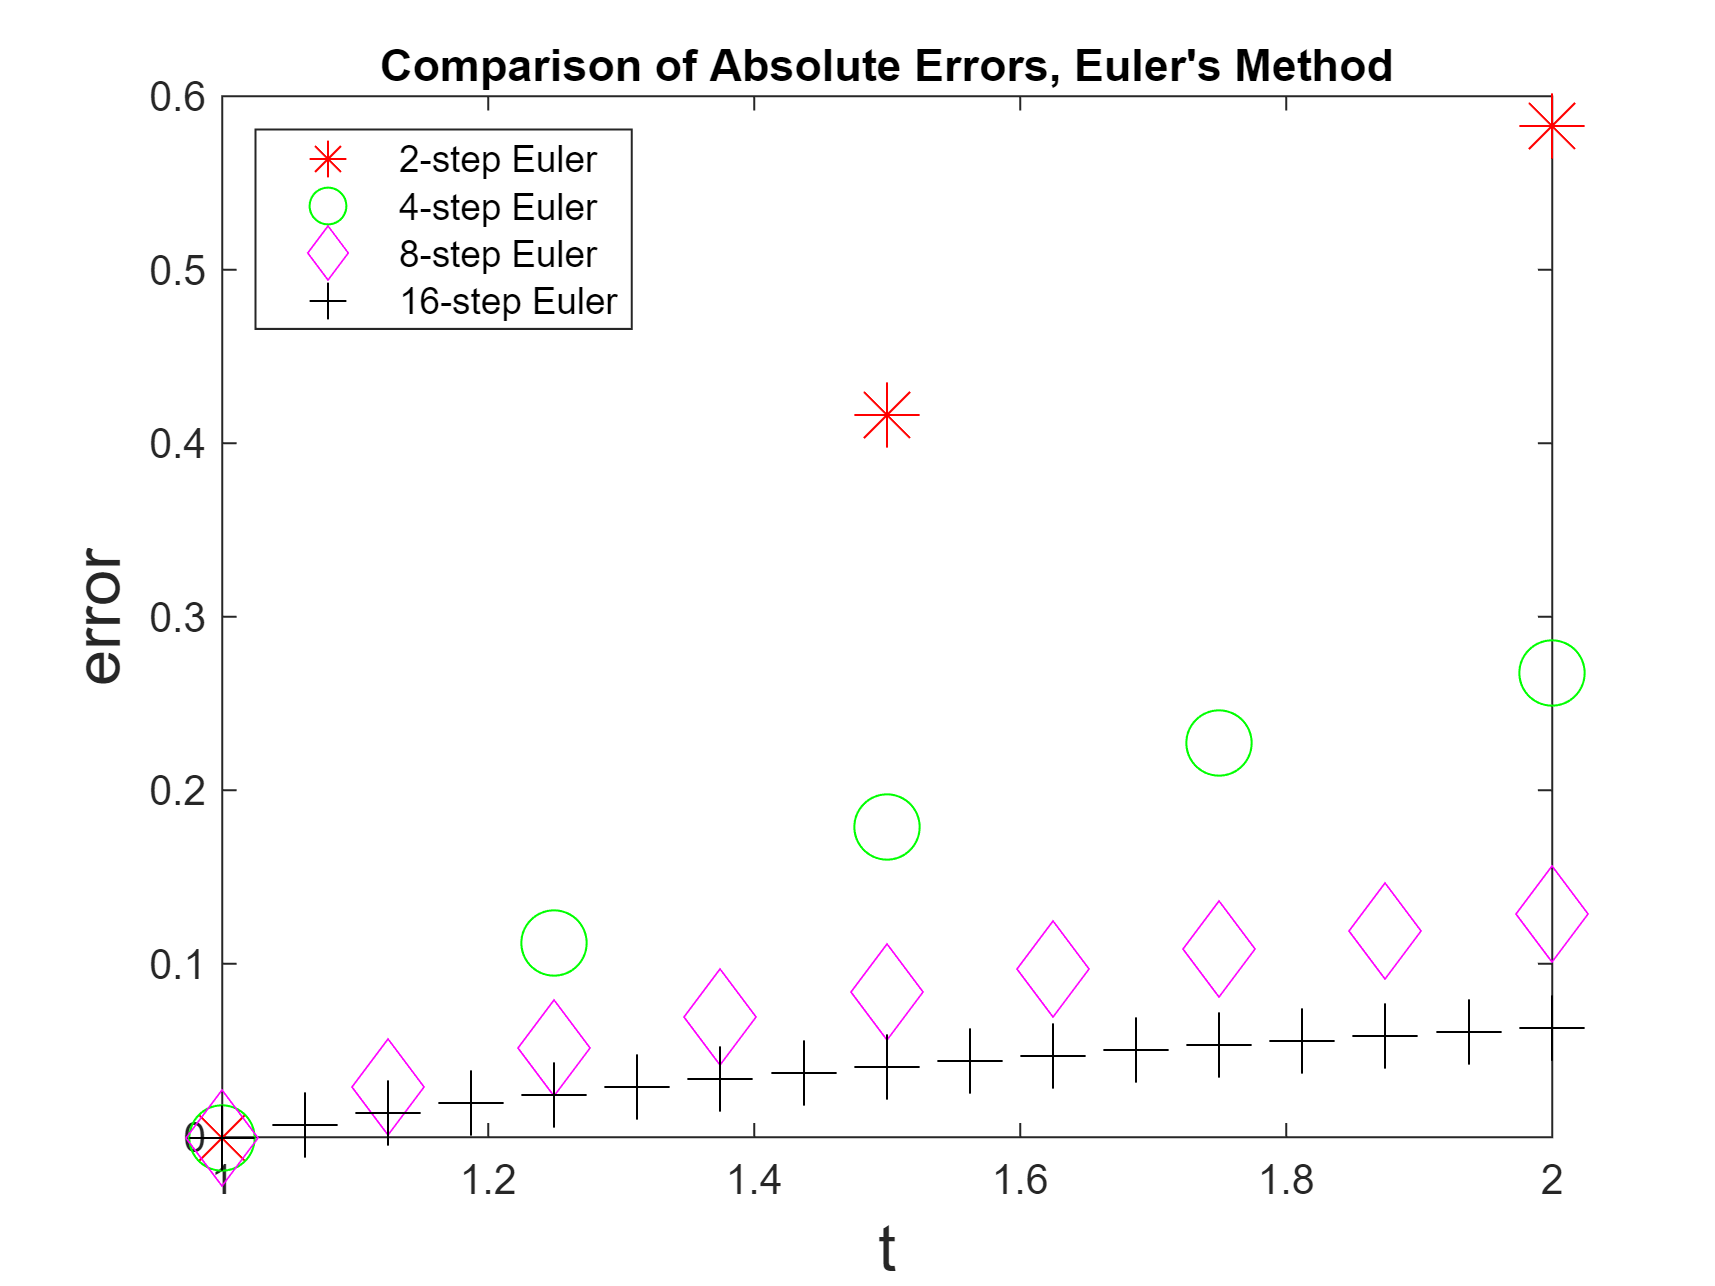

figure(2); hold on; plot(t16, error16, 'k+', 'MarkerSize', 16)
legend('2-step Euler', '4-step Euler', '8-step Euler', '16-step Euler', 'Location', 'NorthWest')

## Exercise 5.2

f = @(t, y) 3 * t - y ./ t;

fdash = @(t, y) 2 * y ./ t.^2;

a = 1;
b = 2;
alpha = 2;

n = 2;

[t, w, h] = taylor2(f, fdash, a, b, alpha, n)

t =     1.0000    1.5000    2.0000


w =     2.0000    3.0000    4.5833


h = 0.5000

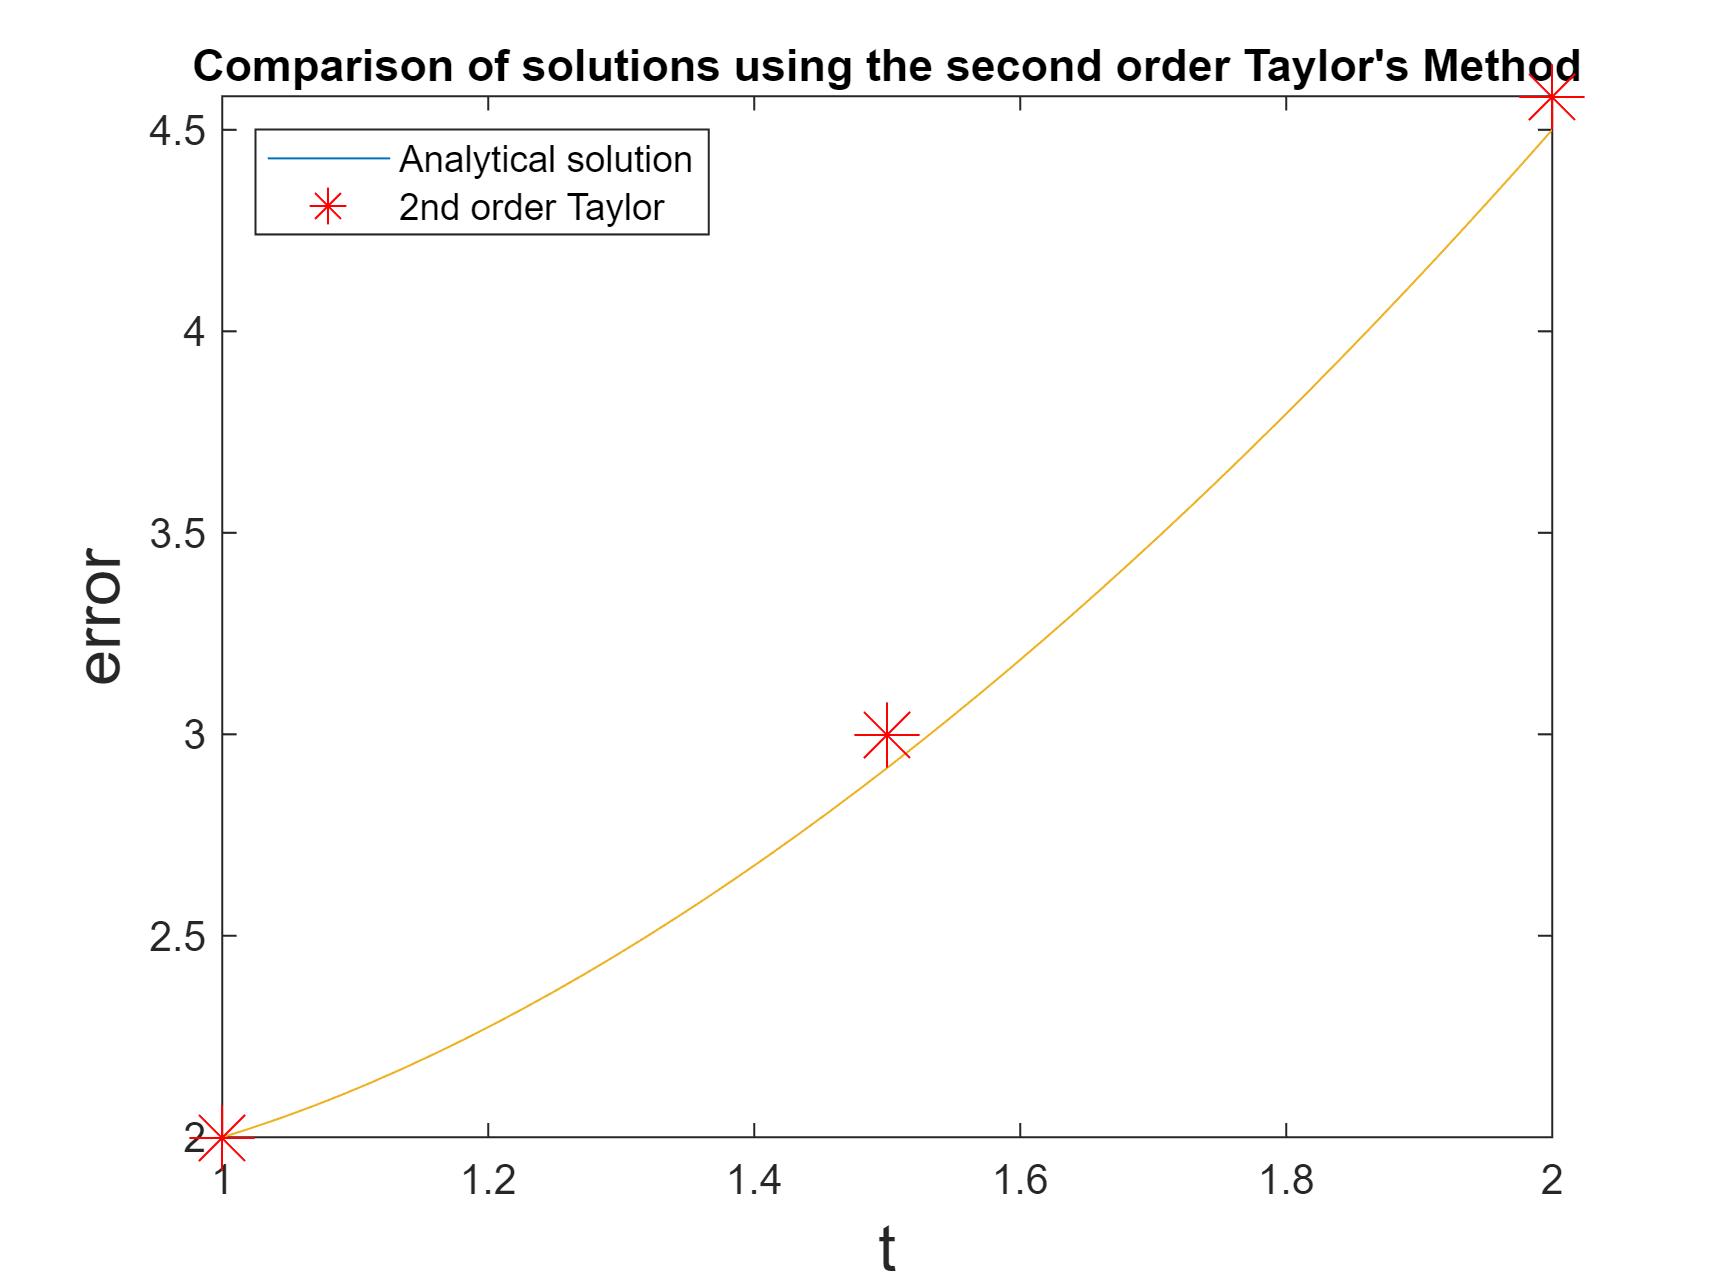

y = @(t) t.^2 + 1 ./ t;

figure(3); 
fplot(y, [a,b]); % plot analytical soln
hold on; 
plot(t, w, 'r*', 'MarkerSize', 16); % add numerical soln to plot
title('Comparison of solutions using the second order Taylor''s Method');
xlabel('t','FontSize',16); ylabel('error','FontSize',16);
legend('Analytical solution', '2nd order Taylor', 'Location', 'NorthWest')

## Exercise 5.3

n = 2;
[t, w, h] = modeuler(f, a, b, alpha, n)

t =     1.0000    1.5000    2.0000


w =     2.0000    2.9583    4.5625


h = 0.5000

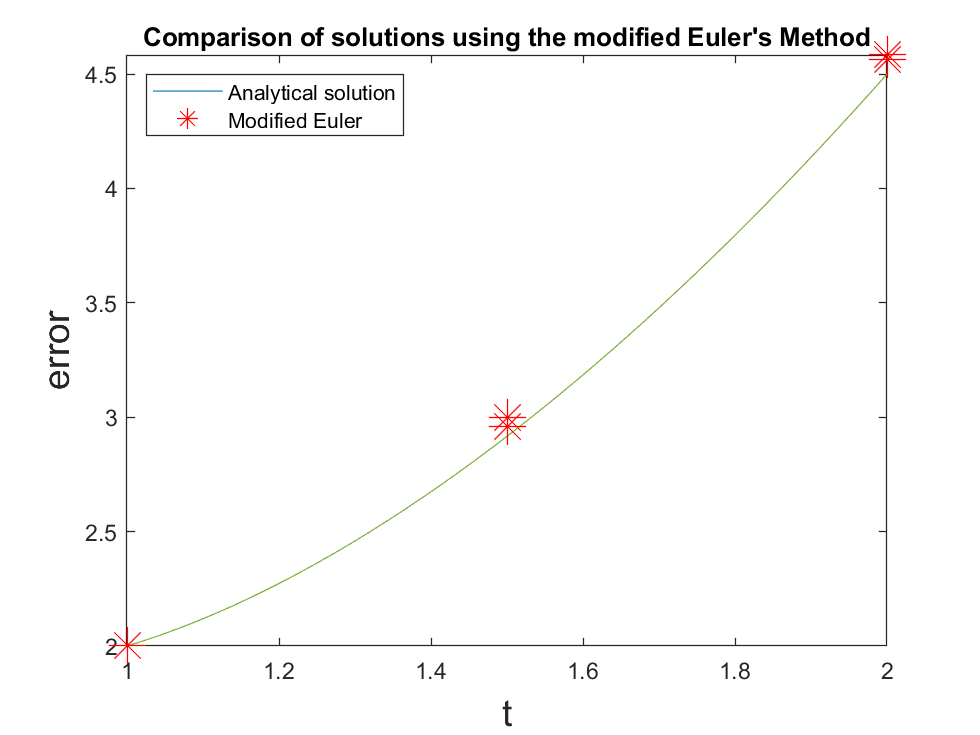


y = @(t) t.^2 + 1 ./ t;

figure(3); 
fplot(y, [a,b]); % plot analytical soln
hold on; 
plot(t, w, 'r*', 'MarkerSize', 16); % add numerical soln to plot
title('Comparison of solutions using the modified Euler''s Method');
xlabel('t','FontSize',16); ylabel('error','FontSize',16);
legend('Analytical solution', 'Modified Euler', 'Location', 'NorthWest')